# Computational Methods in Physics (PHY4605) - **Algorithm and Errors**

## Overview

The term **algorithm** comes from the name of the 9th-century Persian mathematician Al-Khwarizm, which is derived from his Latinized version of his name *Algoritmi*. Al-Khwarizmi wrote a book titled *"Kitab al-Jabr wa-l-Muqabala"* which introduced the concept of using mathematical operations to solve problems. Algorithm development is the process of designing and testing a set of instructions that can be executed by a computer to solve a problem. An algorithm should be clear, concise, effective and independent of any programming language. 

That said, even experienced programmers seldom get programs to run correctly the first time. In computer jargon, an error in a program is called a **bug**. The story is that a hapless moth short-circuited two thermionic valves in one of the earliest computers. This primeval (charcoaled) ‘bug’ took days to find. The process of detecting and correcting such errors is therefore called debugging. There are a number of different types of errors and pitfalls, some of which are peculiar to MATLAB, and some of which may occur when programming in any language.

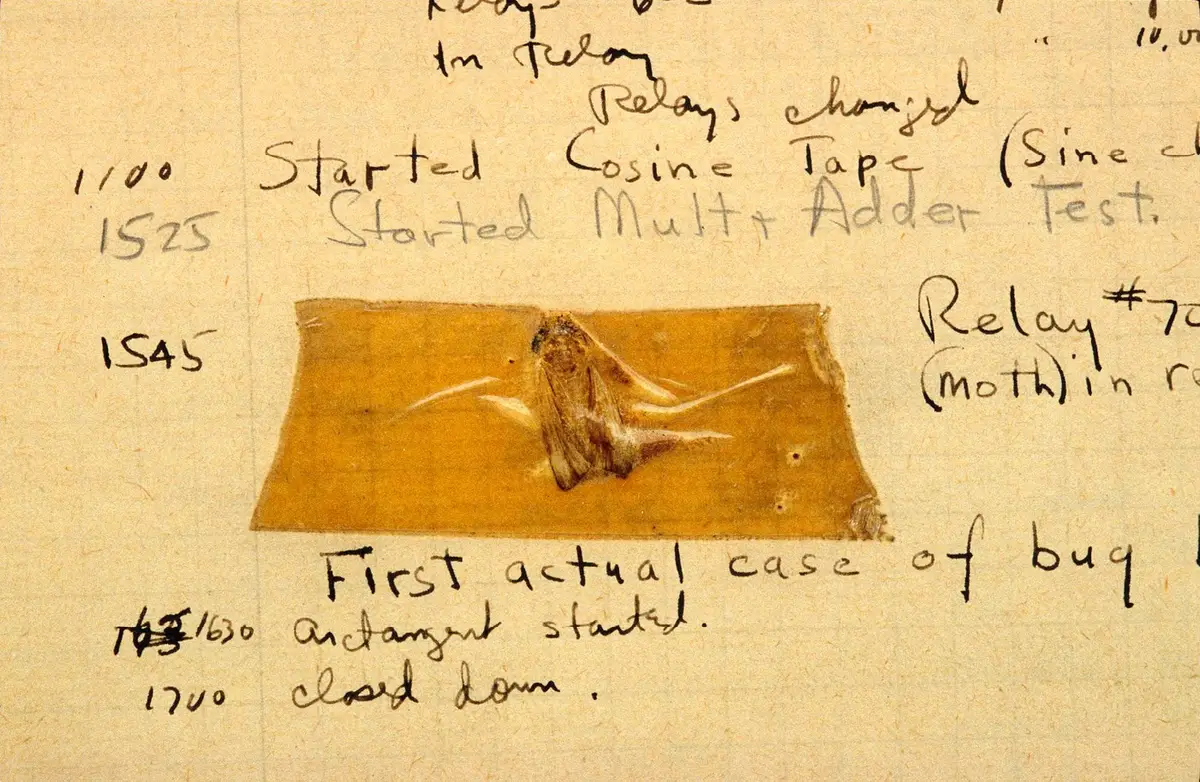

## Algorithm Development

The steps of developing an algorithm are outlined as follows: 

**1. Problem statement**

Develop a detailed statement of the mathematical problem to be solved with a computer program. Consider an example below:

**2. Problem analysis**

The context of the proposed investigation must be established to provide the proper motivation for the design of a computer program. The designer must fully recognize the need and must develop an understanding of the nature of the problem to be solved.

**3. Processing scheme**

Define the inputs required and the outputs to be produced by the program. We need to know: 

**4. Algorithm**

The process of algorithm design involves breaking down the main problem into smaller sub-problems and creating a structure plan consisting of step-by-step tasks written in pseudo-code, which can be easily translated into a computer language. The algorithm for the problem example is as follows:

**5. Program algorithm**

Translate or convert the algorithm into a computer language and debug the syntax errors until the tool executes successfully. We can now program the algorithm using a programming language such as MATLAB:

**6. Evaluation**

The testing and validation step involves comparing the program's results with other programs, experimental data, and theoretical predictions to ensure accuracy, and identifying and correcting any logical or runtime errors that may occur during execution.

**7. Application**

Solve the problems the program was designed to solve. If the program is well designed and useful, it can be saved for future use. In our example, we have calculated the maximum height the ball can reach and the time it takes to reach that height. This information can be used, for example, to determine the range of the ball or to analyze its motion.

### Physics Pinpoint 🔎: Damped Harmonic Oscillator

The small amplitude oscillation of a unit mass attached to a spring is given by the formula $y=e^{-\left(R/2\right)t} \sin \left(\omega t\right)$, where $\omega^2 =\omega_0^2 -R^2 /4$ is the square of the natural frequency of the oscillation with damping (i.e., with resistance to motion); $\omega_0^2 =k$ is the square of the natural frequency of undamped oscillation; $k$ is the spring constant; and $R$ is the damping coefficient. 

Develop a solution procedure by working backwards through the problem statement. Starting at the end of the problem statement, the solution procedure requires the programmer to assign the input variables first followed by the execution of the formula for the amplitude and ending with the output in graphical form. Consider $k=1$ and vary $R$ from 0 to 2 in increments of 0.5. $t$ can be varied through vectorization, while $R$ must be varied through a loop. To plot $y$ versus $t$ for $t$ from 0 to 10 in increments of 0.1, the following script is developed:

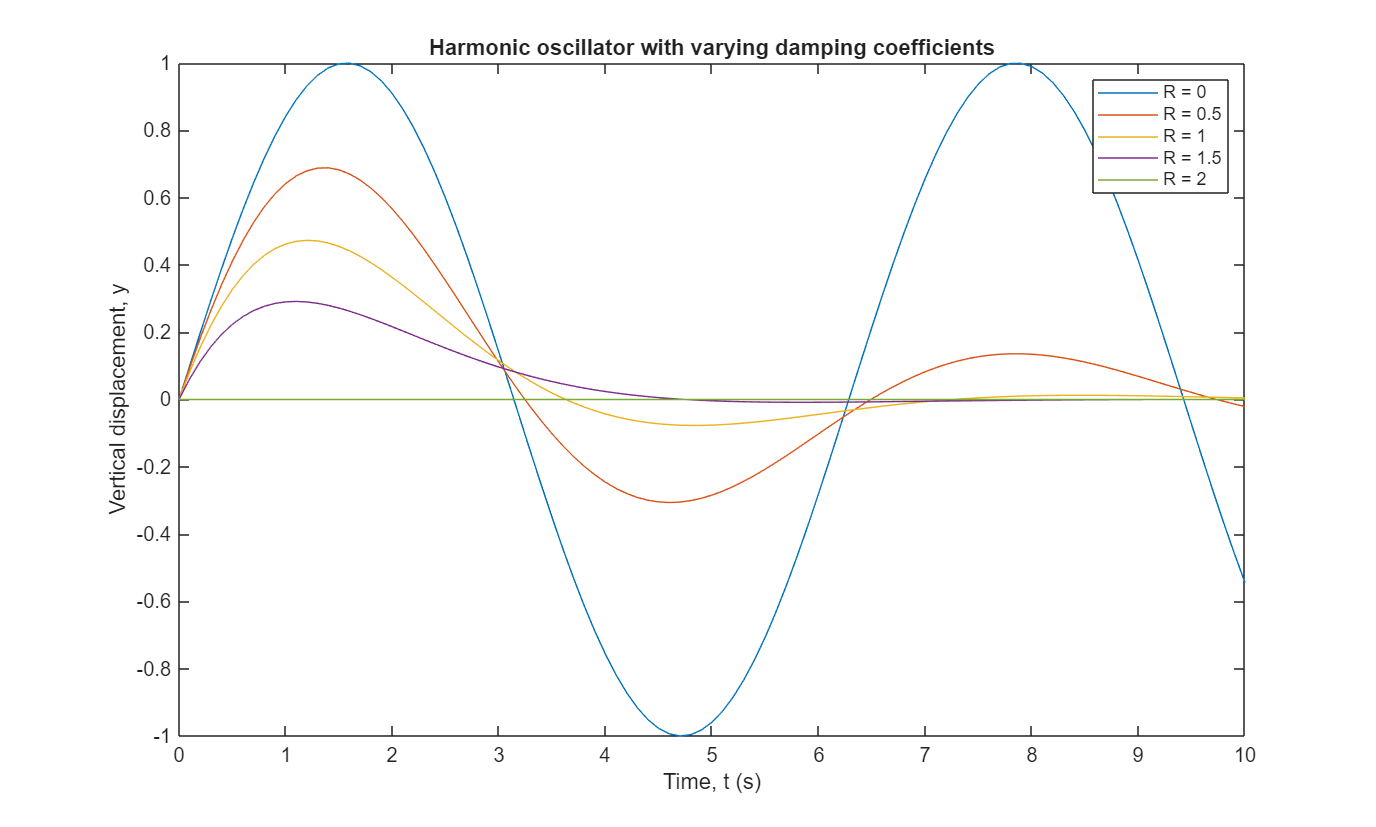

t = 0 : 0.1 : 10;
k = 1;
omega0 = sqrt(k);
for R = 0 : 0.5 : 2
    omega = sqrt(omega0^2 - (R^2)/4);
    y = exp(-R*t/2).*sin(omega*t);
    plot(t, y)
    hold on
end
hold off
LegendTexts = "R = " + string(0 : 0.5 : 2);
legend(LegendTexts);
xlabel('Time, t (s)');
ylabel('Vertical displacement, y');
title('Harmonic oscillator with varying damping coefficients');

### Physics Pinpoint 🔎: Vertical Motion Under Gravity

If a stone is thrown vertically upward with an initial speed $u$, its vertical displacements after an elapsed time $t$ is given by the formula $s=\textrm{ut}-{\textrm{gt}}^2 /2$. Air resistance is ignored. We would like to compute the value of $s$ over a period of about 12.3 seconds at intervals of 0.1 seconds, and plot the distance–time graph over this period. The structure plan for this problem is as follows:

- Assign the data ($g$, $u$ and $t$) to MATLAB variables

- Calculate the value of s according to the formula

- Plot the graph of $s$ against $t$

- Stop

The program to achieve this is:

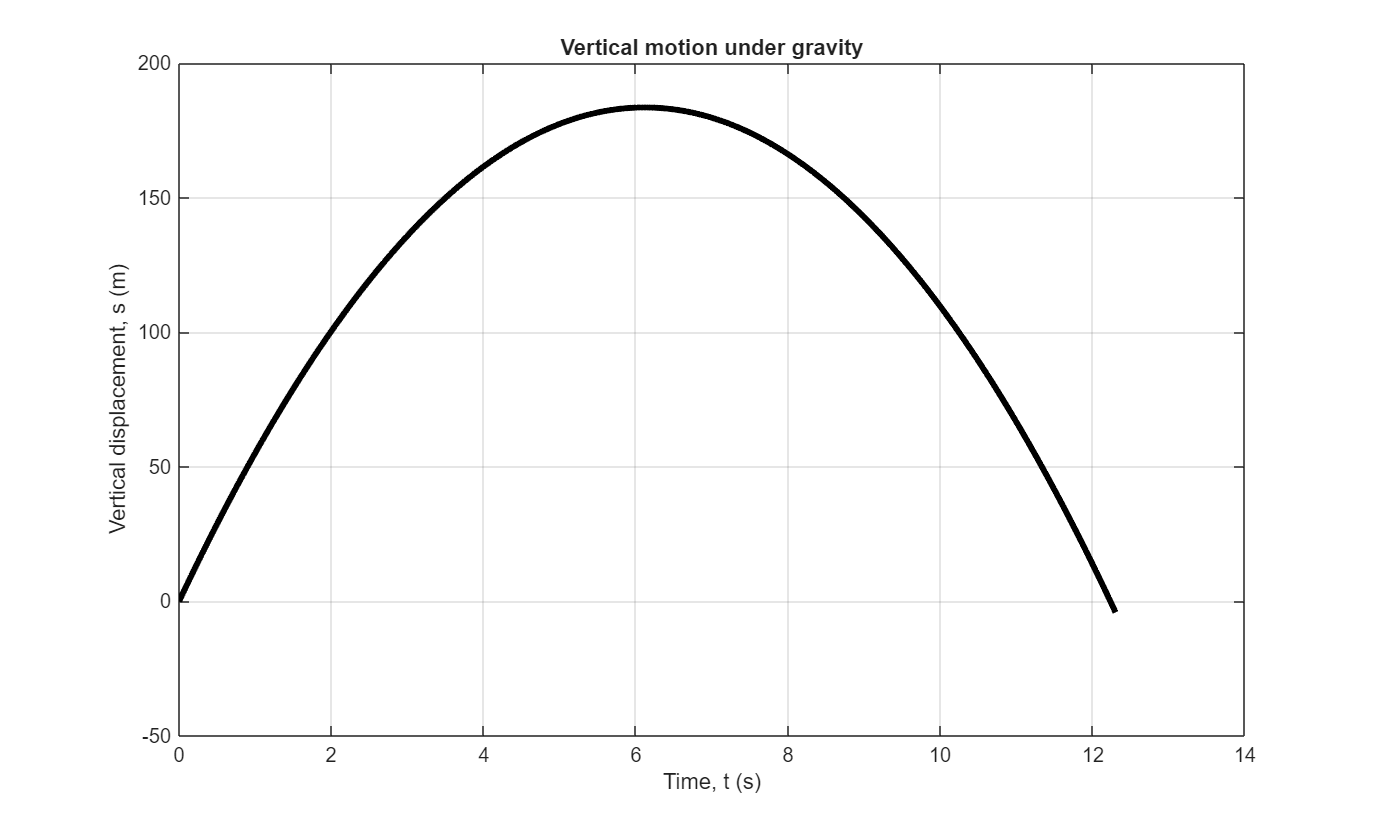

g = 9.81;
u = 60;
t = 0 : 0.01 : 12.3; 
s = u * t - g / 2 * t .^ 2;
plot(t, s,'k','LineWidth',3)
title('Vertical motion under gravity')
xlabel('Time, t (s)'), ylabel('Vertical displacement, s (m)')
grid on

## Errors

### Syntax Errors

Syntax errors are typing errors in MATLAB statements. They are the most frequent type of error, and are fatal, i.e., MATLAB stops execution and displays an error message. Uncomment and run the following commands to examine the error messages.

Missing brackets:

disp(['The answer is ', num2str(2)])

The answer is 2


Misspelled function names:

x = cos(3.14)

x =   -0.999998731727540


Mismatched quotes:

y = "Hello world!"

y = "Hello world!"

Incorrect use of parentheses:

% c = (a+b]

There are many possible syntax errors—you will probably have discovered a few yourself. With experience you will become more adept at spotting your mistakes.

### Logic Errors

These are errors in the actual algorithm you are using to solve a problem, and are the most difficult to find; the program runs, but gives the wrong answers. It’s even worse if you don’t realize the answers are wrong. The following tips might help you to check out the logic:

- Try to run the program for some special cases where you know the answers.

- If you don’t know any exact answers, try to use your insight into the problem to check whether the answers seem to be of the right order of magnitude.

- Try working through the program by hand (or use MATLAB’s excellent interactive debugging facilities).

Suppose we want to compute the sum of the series $1^2 +2^2 +3^2 +\ldotp \ldotp \ldotp$ such that the sum is as large as possible without exceeding 1300. The following script can run and it does give an answer:

Num = 0;
Sum = 0;
while Sum < 1300
    Num = Num + 1;
    Sum = Sum + Num^2;
end
fprintf('Num of terms: %d', Num);

Num of terms: 16

fprintf('Final summation: %d', Sum);

Final summation: 1496

However, it is apparent that the answer is incorrect as the final summation is 1496, which does exceed 1300. The error occurs because the code does not check if adding the next term will cause the sum to exceed 1300. To fix this, we need to modify the loop to check if adding the next term will cause the sum to exceed 1300. If it does, we stop adding terms to the sum and output the number of terms used and the final summation.

Num = 0;
Sum = 0;
while Sum + (Num + 1)^2 < 1300
    Num = Num + 1;
    Sum = Sum + Num^2;
end
fprintf('Num of terms: %d\n', Num);

Num of terms: 15


fprintf('Final summation: %d\n', Sum);

Final summation: 1240


### Rounding Errors

At times, as we have seen, a program will give numerical answers which we know are wrong. This can also be due to rounding error, which results from the finite precision available on the computer, i.e., eight bytes per variable, instead of an infinite number. Run the following program:

X = 0.1;
while X ~= 0.2
    X = X + 0.001;
    fprintf('X = %g, X - 0.2 = %g\n', X, X - 0.2);
end

X = 0.101, X - 0.2 = -0.099
X = 0.102, X - 0.2 = -0.098
X = 0.103, X - 0.2 = -0.097
X = 0.104, X - 0.2 = -0.096
X = 0.105, X - 0.2 = -0.095
X = 0.106, X - 0.2 = -0.094
X = 0.107, X - 0.2 = -0.093
X = 0.108, X - 0.2 = -0.092
X = 0.109, X - 0.2 = -0.091
X = 0.11, X - 0.2 = -0.09
X = 0.111, X - 0.2 = -0.089
X = 0.112, X - 0.2 = -0.088
X = 0.113, X - 0.2 = -0.087
X = 0.114, X - 0.2 = -0.086
X = 0.115, X - 0.2 = -0.085
X = 0.116, X - 0.2 = -0.084
X = 0.117, X - 0.2 = -0.083
X = 0.118, X - 0.2 = -0.082
X = 0.119, X - 0.2 = -0.081
X = 0.12, X - 0.2 = -0.08
X = 0.121, X - 0.2 = -0.079
X = 0.122, X - 0.2 = -0.078
X = 0.123, X - 0.2 = -0.077
X = 0.124, X - 0.2 = -0.076
X = 0.125, X - 0.2 = -0.075
X = 0.126, X - 0.2 = -0.074
X = 0.127, X - 0.2 = -0.073
X = 0.128, X - 0.2 = -0.072
X = 0.129, X - 0.2 = -0.071
X = 0.13, X - 0.2 = -0.07
X = 0.131, X - 0.2 = -0.069
X = 0.132, X - 0.2 = -0.068
X = 0.133, X - 0.2 = -0.067
X = 0.134, X - 0.2 = -0.066
X = 0.135, X - 0.2 = -0.065
X = 0.136, X - 0.2 = -0.06

You will find that you need to crash or stop the program, or else it will run infinitely. The variable `X` never has the value 0.2 exactly, because of rounding error. In fact, `X` misses 0.2 by about $8\ldotp 3\times {10}^{-17}$, as can be seen from displaying the value of `X - 0.2`. It would be better to replace the `while` clause with:

or, even better, with:

### Error Handling

The following statement:

executes the statements in the `try` block and catches resulting errors in the `catch` block. This approach allows you to override the default error behavior for a set of program statements. If any statement in a `try` block generates an error, program control goes immediately to the `catch` block, which contains your error handling statements.

Consider the formula for combinations:


$${}^nC_k=\frac{n!}{k!\left(n-k\right)!}$$


The following code returns the number of combinations of `k` elements from `n` elements.

n = 4
k = 10
Combinations = factorial(n) / (factorial(k) * factorial(n - k))

MATLAB throws an error whenever `k > n`. You cannot construct a set with more elements, `k`, than elements you possess, `n`. 

Using a `try`/`catch` statement, the code automatically exchanges the value of `n` and `k` to avoid the error:

n = 4
k = 10
try
    Combinations = factorial(n) / (factorial(k) * factorial(n - k))
catch Exception
    Combinations = factorial(k) / (factorial(n) * factorial(k - n))
end

Optionally, you can capture more information about errors if a variable follows your `catch` statement. Display the error:

disp(Exception.message)

### Error Debugging

You can diagnose problems in your MATLAB code files by debugging your code interactively in the Editor and Live Editor or programmatically by using debugging functions in the Command Window. There are several ways to debug your code; you can test them on this sample code:

n = 50;
r = rand(n, 1);
plot(r);

m = mean(r);
hold on
yline(m, 'r');
hold off
title('Mean of Random Uniform Data');

**Run to Here**

To explore the state of all variables in the workspace at a specific point in your code, run your code file and then pause. To run code to a specified line and then pause, click the **Run to Here**   button to the left of the line.

When debugging, the **Run to Here**   button becomes the **Continue to Here**   button. For example, click the **Run to Here**   button to the left of line 2. MATLAB runs the code starting at line 1 and pauses before running line 2.

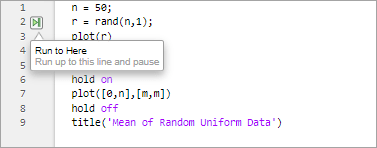

MATLAB indicates the line at which it is paused by using a green arrow and green highlighting:

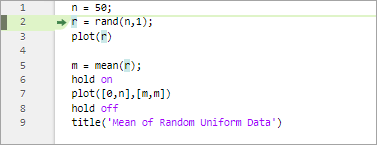

**Add Breakpoints**

If there are lines of code in your file that you want to pause at every time you run your code, add breakpoints at those lines. You can add breakpoints interactively by using the Editor and Live Editor.

There are three types of breakpoints: standard, conditional, and error. To add a standard breakpoint in the Editor or Live Editor, click the gray area to the left of the executable line where you want to set the breakpoint. For example, click the area next to line 3 to add a breakpoint at that line.

When you run the file, MATLAB pauses at the line of code indicated by the breakpoint. The line at which MATLAB is paused does not run until after you continue running your code.

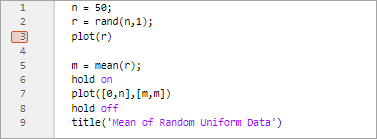

**View Variable Value**

To view the value of a variable while MATLAB is paused, place your cursor over the variable. The current value of the variable appears in a data tip. The data tip stays in view until you move the cursor. To disable data tips, go to the View tab and click the **Datatips **  button off.